%y = exprnd(5,100,1);
y = 10+2*randn(200,1);
%y = [y; 500]; %añadiendo un outlier para ver que pasa
m = bootstrp(200,@mean,y);

%media Bootstrap vs media real
mean(m)

ans = 9.8855

mean(y)

ans = 9.9070


%desviacion estandar de m es sigma/sqrt(n)
2/sqrt(100) %desviacion estandar de m analitica

ans = 0.2000

std(m) %calculo numerico del std de m

ans = 0.1465

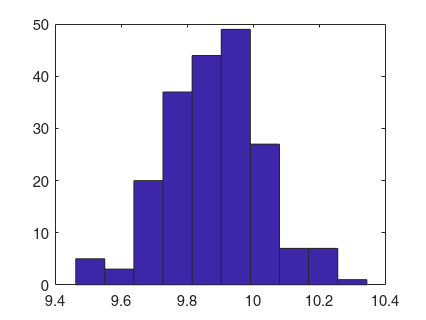


hist(m) %esperamos que se vea normal


%Intervalo de confianza
[h p ci] = ttest(y); ci' %Intervalo de confianza de media con var estimada

ans =     9.6034   10.2107


CIB = [prctile(m,2.5) prctile(m,97.5)] %Intervalo de confianza con bootstrap

CIB =     9.5772   10.1928


Es claro entonces que para la media normal es mejor utilizar el intervalo de confiaza parametrico, pero las tecnicas parametricas se embalan cuando se utilizan otros estadisticos como la mediana

y = exprnd(5,100,1);
y = [y; 500]; %añadiendo un outlier para ver que pasa
m = bootstrp(200,@median,y);

%Al usar una exponencial podemos calcular la mediana real
-5*log(0.5)

ans = 3.4657

%mediana Bootstrap vs mediana muestral
mean(m)

ans = 3.7345

median(y)

ans = 3.7108


%desviacion estandar de m es sigma/sqrt(n)
2/sqrt(100) %desviacion estandar de m analitica

ans = 0.2000

std(m) %calculo numerico del std de m

ans = 0.4278

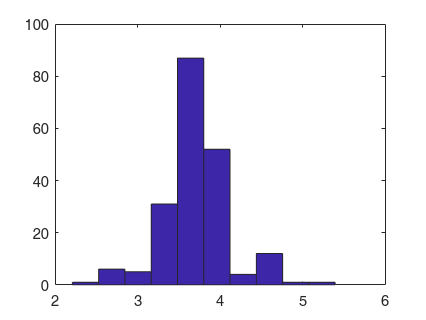


hist(m) %esperamos que se vea normal


%Intervalo de confianza
CIB = [prctile(m,2.5) prctile(m,97.5)] %Intervalo de confianza con bootstrap

CIB =     2.7686    4.6470
